clc;clear;close all;
source = input('your source value: ','s');
x=input('node x: ');
y=input('node y: ');
file=fopen('input4.txt');
n=length(readlines("input4.txt"));
Elemans = Eleman.empty(n:0);
for i=1:n
    line = fgetl(file);
    Elemans(i)= readEleman(line,source);
end
fclose(file);
Elemans=solveC(Elemans,numberOfNodes(Elemans)-1);

$$G = \left(\begin{array}{ccc} \frac{1}{2} & -\frac{1}{2} & 0\\ -\frac{1}{2} & \frac{1}{s}+\frac{1}{2} & -\frac{1}{s}\\ 0 & -\frac{1}{s} & 2\,s+\frac{1}{s} \end{array}\right)$$

$$Is = \left(\begin{array}{ccc} \frac{s}{s^{2}+1} & 0 & 0 \end{array}\right)$$

$$X = \left(\begin{array}{c} \frac{2\,s^{2}+4\,s+1}{2\,\left(s^{2}+1\right)}\\ \frac{2\,s^{2}+1}{2\,\left(s^{2}+1\right)}\\ \frac{1}{2\,\left(s^{2}+1\right)} \end{array}\right)$$

$$Ts = 2$$

$$Vout = \frac{2\,s^{2}+4\,s+1}{2\,\left(s^{2}+1\right)}-\frac{2\,s^{2}+1}{2\,\left(s^{2}+1\right)}$$

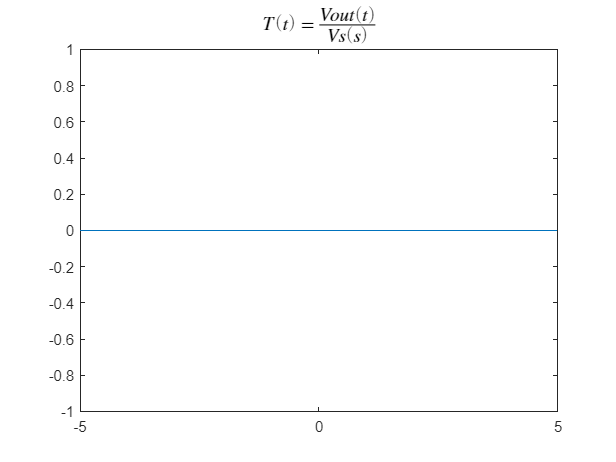

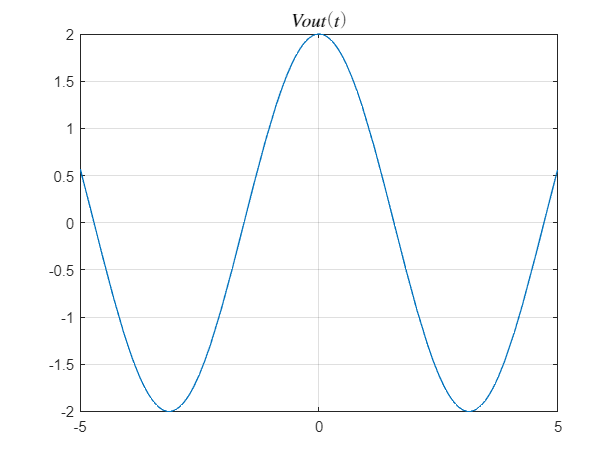

out=fopen('output4.txt','wt');
Finalize(out,Elemans,source,x,y);

fclose(out);




function el = readEleman(inputLine,source)
syms s real
input = split(convertCharsToStrings(inputLine),",");
if(input(1)=="ML")
    el = Eleman(convertStringsToChars(input(1)), ...
        convertStringsToChars(input(2)), ...
        str2double(input(3)), ...
        str2double(input(4)), ...
        str2double(input(5))*s, ...
        convertStringsToChars(input(6)), ...
        str2double(input(7)), ...
        str2double(input(8)), ...
        str2double(input(9))*s, ...
        str2double(input(10))*s);
elseif ((input(1)=='Z')||(input(1)=='H')||(input(1)=='Y')||(input(1)=='T'))
    el = Eleman(convertStringsToChars(input(1)), ...
        convertStringsToChars(input(2)), ...
        str2double(input(3)), ...
        str2double(input(4)), ...
        str2double(input(5)), ...
        str2double(input(6)), ...
        str2double(input(7)),0,0,0);
else
    if((input(1)=="L")||(input(1)=="C"))
        val=str2double(input(5))*s;
    elseif((input(1)=="V")||(input(1)=="I"))
        if(input(5)=='-')
           input(5)=source; 
        end
        val=laplace(str2sym(input(5)));
        
    else
        val=str2double(input(5));
    end
    el = Eleman(convertStringsToChars(input(1)), ...
        convertStringsToChars(input(2)), ...
        str2double(input(3)), ...
        str2double(input(4)),val,0,0,0,0,0);
end
end


%% analysis
%% analysis
function [Els] = solveC(Els,num)
    Admitance = zeros(num+1);
    Source = zeros(1,num+1);
    Admitance=sym(Admitance);
    Source=sym(Source);
    for elem = Els
        if elem.type=='R'
            Admitance(elem.node1,elem.node1) = Admitance(elem.node1,elem.node1)+1./elem.value;
            Admitance(elem.node2,elem.node2) = Admitance(elem.node2,elem.node2)+1./elem.value;
            Admitance(elem.node1,elem.node2) = Admitance(elem.node1,elem.node2)-1./elem.value;
            Admitance(elem.node2,elem.node1) = Admitance(elem.node2,elem.node1)-1./elem.value;
        elseif elem.type=='C'
            Admitance(elem.node1,elem.node1) = Admitance(elem.node1,elem.node1)+elem.value;
            Admitance(elem.node2,elem.node2) = Admitance(elem.node2,elem.node2)+elem.value;
            Admitance(elem.node1,elem.node2) = Admitance(elem.node1,elem.node2)-elem.value;
            Admitance(elem.node2,elem.node1) = Admitance(elem.node2,elem.node1)-elem.value;
        elseif elem.type=='L'
            Admitance(elem.node1,elem.node1) = Admitance(elem.node1,elem.node1)+1./elem.value;
            Admitance(elem.node2,elem.node2) = Admitance(elem.node2,elem.node2)+1./elem.value;
            Admitance(elem.node1,elem.node2) = Admitance(elem.node1,elem.node2)-1./elem.value;
            Admitance(elem.node2,elem.node1) = Admitance(elem.node2,elem.node1)-1./elem.value;
        elseif elem.type=="ML"
            Admitance(elem.node1_1,elem.node1_1) = Admitance(elem.node1_1+1,elem.node1_1)+1./elem.value1;
            Admitance(elem.node2_1,elem.node2_1) = Admitance(elem.node2_1+1,elem.node2_1)+1./elem.value1;
            Admitance(elem.node1_1,elem.node2_1) = Admitance(elem.node1_1+1,elem.node2_1)-1./elem.value1;
            Admitance(elem.node2_1,elem.node1_1) = Admitance(elem.node2_1+1,elem.node1_1)-1./elem.value1;
            Admitance(elem.node1_2,elem.node1_2) = Admitance(elem.node1_2+1,elem.node1_2)+1./elem.value2;
            Admitance(elem.node2_2,elem.node2_2) = Admitance(elem.node2_2+1,elem.node2_2)+1./elem.value2;
            Admitance(elem.node1_2,elem.node2_2+1) = Admitance(elem.node1_2+1,elem.node2_2)-1./elem.value2;
            Admitance(elem.node2_2,elem.node1_2+1) = Admitance(elem.node2_2+1,elem.node1_2)-1./elem.value2;
        elseif elem.type=='H'
            Admitance(elem.node1,elem.dependent_node1) = Admitance(elem.node1,elem.dependent_node1)+elem.value;
            Admitance(elem.node1,elem.dependent_node2) = Admitance(elem.node1,elem.dependent_node2)-elem.value;
            Admitance(elem.node2,elem.dependent_node1) = Admitance(elem.node2,elem.dependent_node1)-elem.value;
            Admitance(elem.node2,elem.dependent_node2) = Admitance(elem.node2,elem.dependent_node2)+elem.value;
        elseif elem.type=='Z'
            Admitance = addRowColumn(Admitance);
            Source = addColumn(Source);
            Admitance(end,elem.dependent_node1) = -elem.value;
            Admitance(end,elem.dependent_node2) = elem.value;
            Admitance(end,elem.node1) = 1;
            Admitance(end,elem.node2) = -1;
            Admitance(elem.node1,end) = 1;
            Admitance(elem.node2,end) = -1;
        elseif elem.type=='T'
            Admitance = addRowColumn(Admitance);
            Source = addColumn(Source);
            Admitance(end,elem.dependent_node1) = 1;
            Admitance(end,elem.dependent_node2) = -1;
            Admitance(elem.dependent_node1,end) = 1;
            Admitance(elem.dependent_node2,end) = -1;
            Admitance(elem.node1,end) = elem.value;
            Admitance(elem.node2,end) = -elem.value;
        elseif elem.type=='Y'
            Admitance = addRowColumn(Admitance);
            Admitance = addRowColumn(Admitance);
            Source = addColumn(Source);
            Source = addColumn(Source);
            Admitance(elem.dependent_node1,end-1) = 1;
            Admitance(elem.dependent_node2,end-1) = -1;
            Admitance(elem.node1,end) = 1;
            Admitance(elem.node1,end) = -1;
            Admitance(end,end) = -elem.value;
            Admitance(end-1,elem.dependent_node1) = 1;
            Admitance(end-1,elem.dependent_node2) = -1;
            Admitance(end,elem.node1) = 1;
            Admitance(end,elem.node2) = -1;
        elseif elem.type=='V'
            Admitance = addRowColumn(Admitance);
            Source = addColumn(Source);
            Source(end) = elem.value;
            Admitance(end,elem.node1) = 1;
            Admitance(end,elem.node2) = -1;
            Admitance(elem.node1,end) = 1;
            Admitance(elem.node2,end) = -1;
        elseif elem.type=='I'
            Source(elem.node1)=Source(elem.node1)-elem.value;
            Source(elem.node2)=Source(elem.node2)+elem.value;
        end
    end
    G=Admitance;
    G(1,:)=[];
    G(:,1)=[]
    Is=Source(2:end)
    X=inv(G)*Is'
    X2=[0 X'];
    n=num+2;
    for i=1:length(Els)
        if Els(i).type == 'V'
            Els(i).voltage = Els(i).value;
            Els(i).current = X2(i);
            n = n + 1;
       elseif Els(i).type == 'I'
           Els(i).current = Els(i).value;
           Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
       elseif Els(i).type == 'R'
           Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
           Els(i).current = Els(i).voltage./Els(i).value;
        elseif Els(i).type == 'C'
           Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
           Els(i).current = Els(i).voltage.*Els(i).value;
        elseif Els(i).type == 'L'
           Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
           Els(i).current = Els(i).voltage./Els(i).value;
           n = n + 1;
        elseif Els(i).type == "ML"
            Els(i).voltage1 = X2(Els.node1_1)-X2(Els(i).node2_1);
            Els(i).current1 = Els(i).voltag2./Els(i).value1;
            n = n + 1;
            Els(i).voltage2 = X2(Els.node1_2)-X2(Els(i).node2_2);
            Els(i).current2 = Els(i).voltage2./Els(i).value2;
            n = n + 1;
        elseif Els(i).type == 'H'
            Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
            Els(i).current = Els(i).voltage.*Els(i).value;
        elseif Els(i).type == 'Z'
            Els(i).voltage = X2(Els(i).node1)-X2(Els(i).node2);
            Els(i).current = X2(n);
            n = n + 1;
        elseif Els(i).type == 'T'
            Els(i).voltage = X2(Els(i).node1+1)-X2(Els(i).node2+1);
            Els(i).current = X2(n).*Els(i).value;
            n = n + 1;
        elseif Els(i).type == 'Y'
            Els(i).voltage = X2(n).*Els(i).value;
            n = n + 1;
            Els(i).current = X2(n);
            n = n + 1;
       end
    end
    
end



function n = numberOfNodes(Elemans)
n=0;
for Eleman = Elemans
    if Eleman.type == "ML"
        if(Eleman.node1_1>n)
            n = Eleman.node1_1;
        end
        if(Eleman.node2_1>n)
            n = Eleman.node2_1;
        end
        if(Eleman.node1_2>n)
            n = Eleman.node1_2;
        end
        if(Eleman.node2_2>n)
            n = Eleman.node2_2;
        end
    else
        if(Eleman.node1>n)
            n = Eleman.node1;
        end
        if(Eleman.node2>n)
            n = Eleman.node2;
        end
        if ((Eleman.type=='Z')||(Eleman.type=='H')||(Eleman.type=='Y')||(Eleman.type=='T'))
            if(Eleman.dependent_node1>n)
                n = Eleman.dependent_node1;
            end
            if(Eleman.dependent_node2>n)
                n = Eleman.dependent_node2;
            end
        end
    end
    
end
end
function A2 = addRowColumn(A)
    A2 = zeros(size(A,1)+1, size(A,2)+1);
    A2=sym(A2);
    A2(1:size(A,1), 1:size(A,2)) = A;
end
function A2 = addColumn(A)
    A2 = zeros(1, size(A,2)+1);
    A2=sym(A2);
    A2(1, 1:size(A,2)) = A;
end
function Finalize(out,Els,source,x,y)
    sourceS=laplace(str2sym(source));
    b=0;
    for E = Els
        if E.type == "ML"
            fprintf(out,"<"+convertCharsToStrings(E.name1)+">.....<"+string(ilaplace(E.voltage1))+">.....<"+string(ilaplace(E.current1))+">\n");
            fprintf(out,"<"+convertCharsToStrings(E.name2)+">.....<"+string(ilaplace(E.voltage2))+">.....<"+string(ilaplace(E.current2))+">\n");
            disp(3);
             if(((E.node1_1==x&&E.node2_1==y)||(E.node1_1==y&&E.node2_1==x))&&b==0)
                b=1;
           Ts= simplify(sourceS.\E.voltage1)
           Tt=ilaplace(Ts);
           Vout=E.voltage1
           Voutt=simplify(ilaplace(Vout));
           fplot(Tt);
          [t,s]= title('$T(t)=\frac{Vout(t)}{Vs(s)}$','interpreter','latex');
          t.FontSize=13;
            figure
           fplot(Voutt)
           [t,s]= title('$Vout(t)$','interpreter','latex');
            t.FontSize=13;
            grid on;
             elseif(((E.node1_2==x&&E.node2_2==y)||(E.node1_2==y&&E.node2_2==x))&&b==0)
                b=1;
           Ts= simplify(sourceS.\E.voltage1)
           Tt=ilaplace(Ts);
           Vout=E.voltage2
           Voutt=simplify(ilaplace(Vout));
           fplot(Tt);
          [t,s]= title('$T(t)=\frac{Vout(t)}{Vs(s)}$','interpreter','latex');
          t.FontSize=13;
            figure
           fplot(Voutt)
           [t,s]= title('$Vout(t)$','interpreter','latex');
            t.FontSize=13;
            grid on;
             end
        else
        fprintf(out,"<"+convertCharsToStrings(E.name)+">.....<"+string(ilaplace(E.voltage))+">.....<"+string(ilaplace(E.current))+">\n"); 
         if(((E.node1==x&&E.node2==y)||(E.node1==y&&E.node2==x))&&b==0)
            b=1;
           %% disp('T(s)= ')
           Ts= simplify(sourceS.\E.voltage)
           Tt=ilaplace(Ts);
           Vout=E.voltage
           Voutt=simplify(ilaplace(Vout));
           fplot(Tt);
          [t,s]= title('$T(t)=\frac{Vout(t)}{Vs(s)}$','interpreter','latex');
          t.FontSize=13;
            figure
           fplot(Voutt)
           [t,s]= title('$Vout(t)$','interpreter','latex');
            t.FontSize=13;
            grid on;
        end
        end
       
    end
end

